# **RS-HL-7: MDP-DP Analysis of Code**

**Hongseok Kim**

**UT Austin Oden Institute**

**6/28/2024**

## Scope

- Code description for RS-HL-5 Satellite Network Design Structure.

- 5-level hierarchy data structure code using MDP-DP framework is described.

## IV. Code of MDP-DP Satellite Network Structure

### IV.1 Variables Initializtion

% clear;clc;


% Define destination satellite number
destination_state = 38;


% 1.1 Initialize the MDP Structure (Level 1)
MDP = struct();

% 1.2 Load the Satellite Contat Dataset
load('/workspace/RS_Dataset/RS_HL_3_dataset.mat')

% 1.2.1 Select Elapsed time slot for the simulation: 
%   15 seconds timestep,so n time_indices indicates start time = 15*n seconds

time_index = 1;
sat_to_sat_contact_matrix = sat_to_sat_contact_3d_matrix(:,:,time_index);

% 1.3 Initialize the State level (Level 2)
number_of_states = length(sat_to_sat_contact_matrix(:,1));

for state_index = 1:number_of_states
  MDP.(['state' num2str(state_index)]) = {};
end

% 1.4 Find available actions (availabe SATs to contact) from each state

% Sample available contact sats from single sat
sample_1 = find(sat_to_sat_contact_matrix(1,:) == 1);


% 1.5 Initilize the Action level (Level 3)

number_of_states = length(sat_to_sat_contact_matrix(:,1));
for state_index = 1:number_of_states
  % 1.5.1 Find the available next state candidates for each current state
  next_state_candidates = find(sat_to_sat_contact_matrix(state_index,:) == 1);
  number_of_actions = length(next_state_candidates);

  % 1.5.2 Initialize Action String Array (Level 3-1)
  for action_index = 1:number_of_actions
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]) = {};
  end
  % 1.5.3 Initialize State Value Array with 0 (Level 3-2)
    MDP.(['state' num2str(state_index)]).('state_value') = 0; % Starting with 0
end


% 1.6 Initialize Next State Level (Level 4)

for state_index = 1:number_of_states
  next_state_candidates = find(sat_to_sat_contact_matrix(state_index,:) == 1);
  number_of_actions = length(next_state_candidates);
  for action_index = 1:number_of_actions
    % 1.6.1 Initialize Next State Double Array (Level 4-1 = 3-1-1) 
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('next_state') = {};
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('fail').('next_state') = {};
    % 1.6.2 Intialize Action value Array (Level 4-2 = 3-1-2)
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]). ...
        ('action_value') = {};
    % 1.6.3 Initialize Policy Function Double Array (Level 4-3 = 3-1-3)
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]). ...
        ('policy_function') = 1/number_of_actions; % Equally distributing the probability
  end
end


% 1.7 Initialize State Transition and Reward Level (Level 5)

for state_index = 1: number_of_states
  next_state_candidates = find(sat_to_sat_contact_matrix(state_index,:) == 1);
  number_of_actions = length(next_state_candidates);
  for action_index = 1:number_of_actions


   % 1.7.1 Initialize Next State Double Array (Level 5-1 = 4-1-1) 
    % 1.7.1.1 Case 1: Action is success 
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]). ...
         ('success').('next_state') =  next_state_candidates(action_index); 
    % 1.7.1.2 Case 2: Action is failure
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]). ...
         ('fail').('next_state') = state_index;
   
   % 1.7.2 Define State transition Probability T (Level 5-2 = 4-1-2)
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]). ...
        ('success').('transition_probability') = 0.8;
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]). ...
        ('fail').('transition_probability') = 0.2;

   % 1.7.3 Define Reward R (Level 5-3 = 4-1-3)

    % 1.7.3.1 Define Failure Reward = -50
    MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('fail').('reward') = -30;

    current_state = state_index;
    next_state = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('next_state');

    % 1.7.3.2 If success but returning to current state: Reward = -50
    if current_state == next_state
        MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward') = -30;
    end

    % 1.7.3.3 Regular Transition: 
    % Same orbit reward = -1, Different orbit reward = -1
     if current_state < 25
        if next_state < 25
            MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward') = -1;
        end
        if next_state > 23
            MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward') = -15;
        end
     end

     if current_state > 23
        if next_state > 23
            MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward') = -1;
        end
        if next_state < 25
            MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward') = -15;
        end
     end
  end
end



% 1.8 Define Destination state

MDP = rmfield(MDP, ['state' num2str(destination_state)]);
MDP.(['state' num2str(destination_state)]).('state_value') = 0;
MDP.(['state' num2str(destination_state)]).(['action' num2str(1)]).('action_value') = {};
MDP.(['state' num2str(destination_state)]).(['action' num2str(1)]).('policy_function') = 1;
MDP.(['state' num2str(destination_state)]).(['action' num2str(1)]).('success').('next_state') = destination_state;
MDP.(['state' num2str(destination_state)]).(['action' num2str(1)]).('success').('transition_probability') = 1;
MDP.(['state' num2str(destination_state)]).(['action' num2str(1)]).('success').('reward') = 0;
MDP.(['state' num2str(destination_state)]).(['action' num2str(1)]).('fail').('next_state') = destination_state;
MDP.(['state' num2str(destination_state)]).(['action' num2str(1)]).('fail').('transition_probability') = 0;
MDP.(['state' num2str(destination_state)]).(['action' num2str(1)]).('fail').('reward') = 0;


% 1.9 update corresponding reward function based on destination state

for state_index = 1: number_of_states
   % We don't count the case of destination state: already defined 
  if state_index == destination_state
      continue
  end

  next_state_candidates = find(sat_to_sat_contact_matrix(state_index,:) == 1);
  number_of_actions = length(next_state_candidates);
  for action_index = 1:number_of_actions

    % 1.9.1 Define State transition Probability T (Level 5-2 = 4-1-2)
    current_state = state_index;
    next_state = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('next_state');

    % 1.9.2 Filter: Next state is destination state
    if next_state == destination_state

    % 1.9.3 Positive Reward function for Next state is destination case
    % Same orbit reward = 100, Different orbit reward = 50
     if current_state < 25
        if next_state < 25
            MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward') = 100;
        end
        if next_state > 23
            MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward') = 50;
        end
     end

     if current_state > 23
        if next_state > 23
            MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward') = 100;
        end
        if next_state < 25
            MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward') = 50;
        end
     end
    end
  end
end


### VI.2 Policy Evaluation

pi_distribution = zeros(number_of_states);
pi_distribution_updated = zeros(number_of_states);

policy_iteration_count = 1;


state_value_struct = struct();
state_value_matrix_cumulative = [];
value_iteration_no = [];

% Start of the Algorithm
while true

% Initialize pi_distribution

gamma = 0.99;

tolerance = 1e-1;
max_iterations = 1000;
Delta = inf; 
value_iteration_count = 0;

state_value_matrix = [];


while(abs(Delta) > tolerance) && (value_iteration_count < max_iterations)
    Delta_vector = zeros(number_of_states,1);


    state_value_vector = zeros(1,number_of_states);

    for state_index = 1:number_of_states

        next_state_candidates = find(sat_to_sat_contact_matrix(state_index,:) == 1);
        number_of_actions = length(next_state_candidates);

        if state_index == destination_state
        number_of_actions = 1;
        end


        v = MDP.(['state' num2str(state_index)]).state_value;
        v_update = 0;    


        for action_index = 1:number_of_actions
            T_s = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('transition_probability');
            r_s = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('reward');
            T_f = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('fail').('transition_probability');
            r_f = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('fail').('reward');
            s_s = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('success').('next_state');
            s_f = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('fail').('next_state');
            v_s_s = MDP.(['state' num2str(s_s)]).('state_value');
            v_s_f = MDP.(['state' num2str(s_f)]).('state_value');

            q_s_a = T_s * (r_s + gamma* v_s_s) + T_f * (r_f + gamma* v_s_f);
            MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('action_value') = q_s_a;

            pi = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('policy_function');

            v_update = v_update + pi*q_s_a;
        end

       MDP.(['state' num2str(state_index)]).state_value = v_update;
       Delta_vector(state_index) = abs(v_update-v);
       v = v_update;
       state_value_vector(state_index) = v_update; 
    end

    state_value_matrix = [state_value_matrix; state_value_vector];
    state_value_matrix_cumulative = [state_value_matrix_cumulative;state_value_vector];

    Delta = max(Delta_vector);
    value_iteration_count = value_iteration_count + 1;
    if value_iteration_count >= max_iterations
        fprintf('Maximum number of iterations reached for state %d\n', state_index);
    end
end
state_value_struct.(['iteration' num2str(policy_iteration_count)]) = state_value_matrix;
value_iteration_no = [value_iteration_no; length(state_value_matrix(:,1))];
state_value_matrix = [];

### VI.3 Policy Improvement 

for state_index = 1:number_of_states

    next_state_candidates = find(sat_to_sat_contact_matrix(state_index,:) == 1);
    number_of_actions = length(next_state_candidates);

    if state_index == destination_state
      number_of_actions = 1;
    end

    action_value_vector = zeros(number_of_actions,1);

    for action_index = 1:number_of_actions
    action_value_vector(action_index) = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('action_value');
    end

    maximum_action_value = max(action_value_vector);
    argmax_a = find(action_value_vector == maximum_action_value);
    for action_index = 1:number_of_actions
      if any(action_index == argmax_a)
        MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('policy_function') = 1/length(argmax_a);
      else
        MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('policy_function') = 0; 
      end

    pi_distribution_updated(state_index,action_index) = MDP.(['state' num2str(state_index)]).(['action' num2str(action_index)]).('policy_function');


    end
end

   if pi_distribution == pi_distribution_updated
       break;
   end

   pi_distribution = pi_distribution_updated;
   policy_iteration_count = policy_iteration_count +1;

end

total_policy_iteration = policy_iteration_count;

rl_result =      2     0
     1    -1
    24   -16
    45   -17
    44   -18
    18   -33
    39   -48
    38    52


## V. Test

state_list = zeros(number_of_states,1);

total_policy_iteration = 7

reward_list = zeros(number_of_states,1);

value_iteration_no =    191
    13
     5
     5
     5
     4
     7



start_state = 2;

Final_state_value =     1.0000    4.6129
    2.0000   -3.9234
    3.0000   -2.8527
    4.0000    5.7196
    5.0000   14.3812
    6.0000   23.1490
    7.0000   32.0271
    8.0000   41.0174
    9.0000   50.1211
   10.0000   59.3398


state_list(1) = start_state;
index = 1;
cumulative_reward = 0;

while index < 50

total_policy_iteration = 7

value_iteration_no =    191
    13
     5
     5
     5
     4
     7


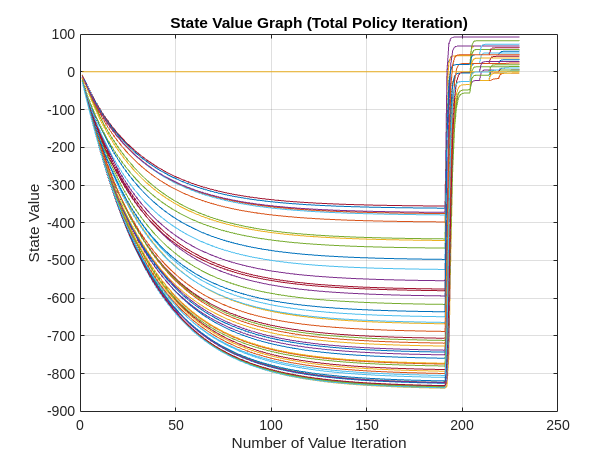

current_state = state_list(index);

action_number = find(pi_distribution(current_state,:));

if length(action_number) > 1
  action_number = randsample(action_number,1);
end

next_state = MDP.(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('next_state');
reward = MDP.(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('reward');
cumulative_reward = cumulative_reward + reward;



index = index + 1;


if current_state == destination_state
    break
end

reward_list(index) = cumulative_reward;
state_list(index) = next_state;
end

state_list = state_list(state_list ~= 0);
reward_list = reward_list(reward_list ~= 0);
rl_result = [state_list, [0;reward_list]]


## VI. Data and Performance Analysis

### VI.0 State Value Matrix final Status

total_policy_iteration
value_iteration_no
A = state_value_struct.(['iteration' num2str(total_policy_iteration)]);
Final_state_value = [(1:48)', A(value_iteration_no(total_policy_iteration),:)']

### VI.1 State Value Graph

#### VI.1.1 Iteration Information

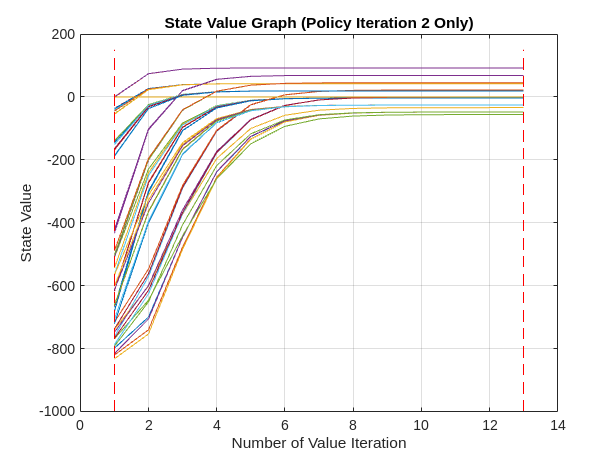

total_policy_iteration

value_iteration_no

#### VI.1.2 Total Policy Iteration

total_iteration = length(state_value_matrix_cumulative(:,1));
for i = 1:number_of_states
plot(1:total_iteration,state_value_matrix_cumulative(:,i))
hold on
end

hold off
grid on
title('State Value Graph (Total Policy Iteration)');
xlabel('Number of Value Iteration')
ylabel('State Value')

#### V.1.4 Policy Iteration 2 Only

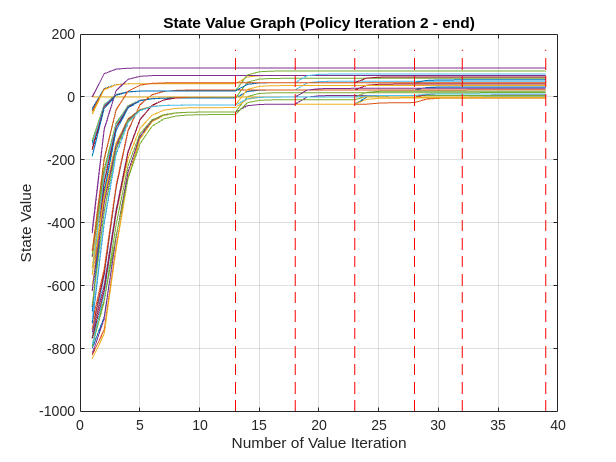

total_iteration = value_iteration_no(2);
start_ind = value_iteration_no(1) +1;
end_ind = value_iteration_no(1) + value_iteration_no(2);

for i = 1:number_of_states

    plot(1:total_iteration,state_value_matrix_cumulative(start_ind:end_ind,i))
hold on
end

for j = 2:3
policy_iteration_point = [1,value_iteration_no(2)];
y = linspace(-1000,150);
x = ones(length(y),1)*policy_iteration_point;
plot(x,y,'LineStyle','--','Color','r')
end


hold off
grid on
title('State Value Graph (Policy Iteration 2 Only)');
xlabel('Number of Value Iteration')
ylabel('State Value')

#### V.1.5 Policy Iteration 2 - End

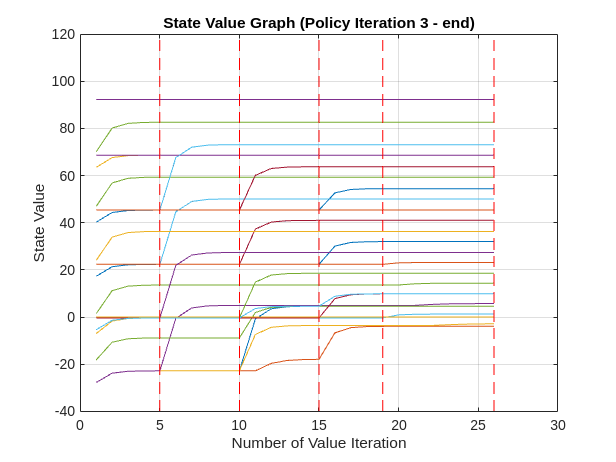

start_ind =  value_iteration_no(1) +1;

total_iteration = length(state_value_matrix_cumulative(start_ind:end,1));
for i = 1:number_of_states
    plot(1:total_iteration,state_value_matrix_cumulative(start_ind:end,i))

hold on
end

for j = 2:total_policy_iteration
policy_iteration_point = sum(value_iteration_no(2:j));
y = linspace(-1000,150);
x = ones(length(y),1)*policy_iteration_point;
plot(x,y,'r','LineStyle','--','Color','r')
end
hold off
grid on
title('State Value Graph (Policy Iteration 2 - end)');
xlabel('Number of Value Iteration')
ylabel('State Value')

#### V.1.6 Policy Iteration 3-End

start_ind =  value_iteration_no(1) + value_iteration_no(2) +1;


total_iteration = length(state_value_matrix_cumulative(start_ind:end,1));
for i = 1:number_of_states
    plot(1:total_iteration,state_value_matrix_cumulative(start_ind:end,i))
hold on
end


for j = 3:total_policy_iteration
policy_iteration_point = sum(value_iteration_no(3:j));
y = linspace(-40,120);
x = ones(length(y),1)*policy_iteration_point;
plot(x,y,'LineStyle','--','Color','r')
end


hold off
grid on
title('State Value Graph (Policy Iteration 3 - end)');
xlabel('Number of Value Iteration')
ylabel('State Value')

### VI.2 Generated Network Path

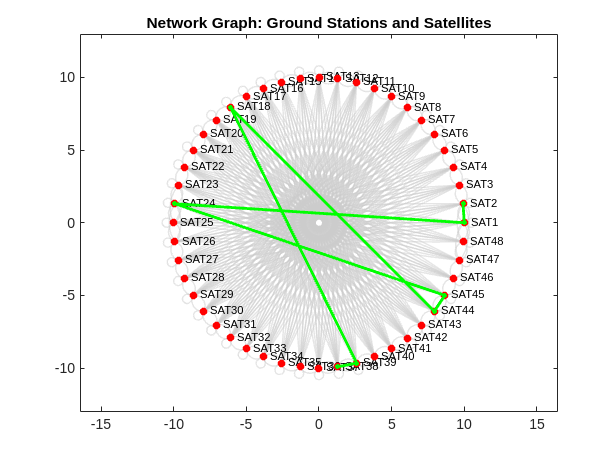

% Number of ground stations and satellites
num_sats = 48;

% Create a graph object
G = graph();

% Load the Satellite Contact Matrix
Sat_to_Sat = sat_to_sat_contact_3d_matrix(:,:,time_index);

% Add Satellites as nodes
for i = 1:num_sats
    G = addnode(G, sprintf('SAT%d', i));
end



% Add edges between Satellites
for i = 1:num_sats
    for j = 1:num_sats
        if Sat_to_Sat(i, j) == 1
            G = addedge(G, sprintf('SAT%d', i), sprintf('SAT%d', j));
        end
    end
end

pi = 3.1415026535;
satellite_radius = 10;

% Satellite positions
satellite_angles = linspace(0, 2*pi, num_sats+1);
satellite_angles = satellite_angles(1:end-1);
satellite_x = satellite_radius * cos(satellite_angles);
satellite_y = satellite_radius * sin(satellite_angles);

% Load the Dataset Handovering Sequence
Data_Transmission_Sequence = zeros(length(state_list),2);

for ii = 1:length(state_list)
Data_Transmission_Sequence(ii,:) =[satellite_x(state_list(ii)), satellite_y(state_list(ii))];
end



% Plot the network graph
figure;
plot(G, 'XData', satellite_x, 'YData', satellite_y, 'NodeColor', [0.6 0.6 0.6], 'EdgeColor', [0.8 0.8 0.8], 'LineWidth', 1);
hold on;

% Plot the ground stations in blue and the satellites in red
plot(satellite_x, satellite_y, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');

plot(Data_Transmission_Sequence(:,1),Data_Transmission_Sequence(:,2),'go', 'MarkerSize', 3, 'MarkerFaceColor', 'G')
plot(Data_Transmission_Sequence(:,1),Data_Transmission_Sequence(:,2),'g','LineWidth',2);

% Adjust the axis limits to fit the plot
axis equal;
title('Network Graph: Ground Stations and Satellites');